clc;
clear all;
clf;

This script showcases the ephemeris intake from Starlink. You will need to provide the location of the .zip files from space-track.org. 

addpath("../Utils/")
addpath("../data/")
%--------------------------------------%
%----------------Params----------------%
%--------------------------------------%

files = {'..\data\SpaceX_Ephemeris_552_SpaceX_2022-12-16UTC05_21_02_1.zip',
         '..\data\SpaceX_Ephemeris_552_SpaceX_2022-12-16UTC05_21_02_2.zip',
         '..\data\SpaceX_Ephemeris_552_SpaceX_2022-12-16UTC05_21_02_3.zip'};

Provide a Starlink SV id to locate it in the files and grab the ephemerides. Specify a time from the start of the provided data, and a duration. Also, for plotting over eart, specify a receiver location and add an example from MATLAB to take advantage of the earth map.

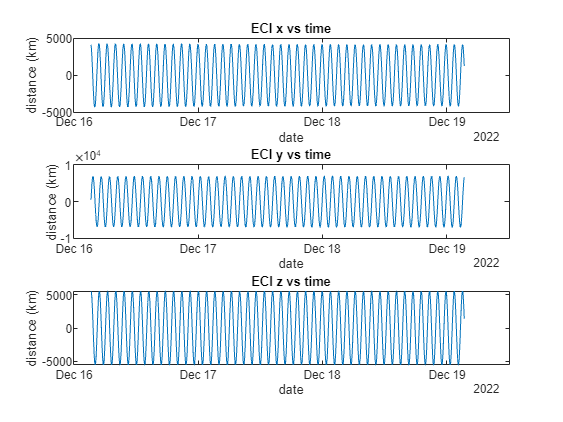

StrlkId = 2580;
verbose = 0;
tstart = 0; % minutes from beginning of file
tdur = 72*60;% minutes (data sampled at 60 seconds)
rx_lla = [30.290931567761696, -97.73707866668703, 176];
addpath("D:\Documents\MATLAB\Examples\R2023a\map\DrapeGeoidHeightsOverTopographyExample")
%--------------------------------------%
%------------Grab Ephemerides----------%
%--------------------------------------%
% -- Get ephemerides from files
data = getEphSpaceTrackZip(files, StrlkId,verbose);
if (isempty(data))
    return
end

%--------------------------------------%
%----------Dependednt Params-----------%
%--------------------------------------%
rx_ECEF =  lla2ecef(rx_lla)'./1e3; % in km

% -- Select segment
Nsamp = tdur;
Nstart = max(tstart,1);
range = Nstart:(Nsamp+Nstart);
if (Nsamp+Nstart > length( data.epoch_datetime))
    Nsamp = length( data.epoch_datetime)-Nstart;
    range = Nstart:length(data.epoch_datetime);
end
data.epoch_datetime = data.epoch_datetime(range);
data.epoch_state = data.epoch_state(:,range);
data.epoch_covariance = data.epoch_covariance(:,:,range);


[y,mo,d] = ymd(data.epoch_datetime);
[h,mi,s] = hms(data.epoch_datetime);
tm = [y',mo',d',h',mi',s'];
data.epoch_state_ECEF = zeros(3,Nsamp);
for ii = 1:length(data.epoch_datetime)
    [r_ecef,v_ecef,a_ecef] = eci2ecef(tm(ii,:),data.epoch_state(1:3,ii));
    data.epoch_state_ECEF(:,ii) = r_ecef;
end


%--------------------------------------%
%----------------Plots-----------------%
%--------------------------------------%
figure(1)
subplot(3,1,1)
plot(data.epoch_datetime,data.epoch_state(1,:))
title("ECI x vs time")
ylabel("distance (km)")
xlabel("date")
subplot(3,1,2)
plot(data.epoch_datetime,data.epoch_state(2,:))
title("ECI y vs time")
ylabel("distance (km)")
xlabel("date")
subplot(3,1,3)
plot(data.epoch_datetime,data.epoch_state(3,:))
title("ECI z vs time")
ylabel("distance (km)")
xlabel("date")



f = figure(2);
plotEarth(f,rx_lla)

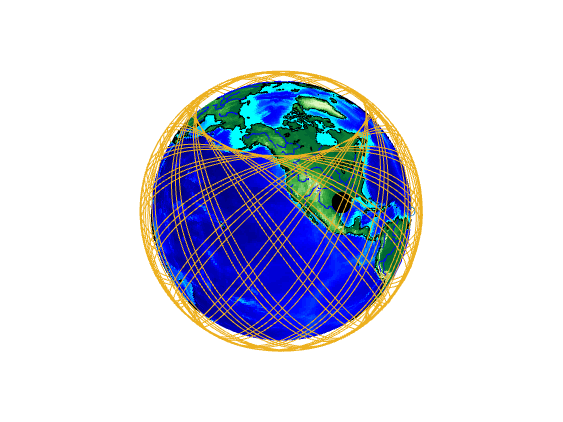


alpha = 1;
hold on
axis equal
comet3(data.epoch_state_ECEF(1,:),data.epoch_state_ECEF(2,:),data.epoch_state_ECEF(3,:))
hold off
title("Trace of orbit around earth over 72 Hours")

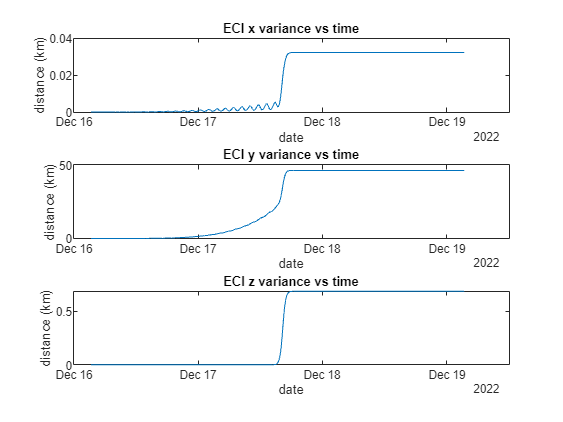


figure(3)
subplot(3,1,1)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(1,1,:)))
title("ECI x variance vs time")
ylabel("distance (km)")
xlabel("date")
subplot(3,1,2)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(2,2,:)))
title("ECI y variance vs time")
ylabel("distance (km)")
xlabel("date")
subplot(3,1,3)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(3,3,:)))
title("ECI z variance vs time")
ylabel("distance (km)")
xlabel("date")

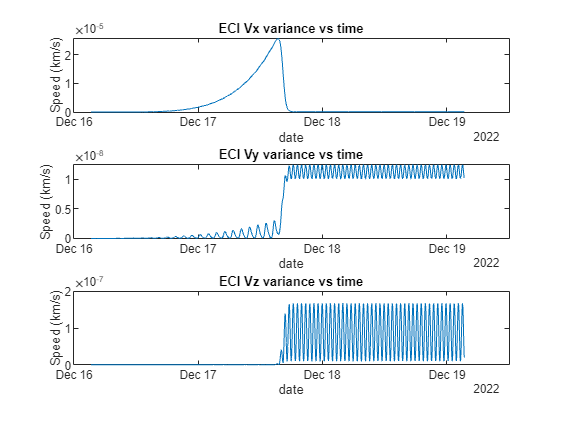


figure(4)
subplot(3,1,1)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(4,4,:)))
title("ECI Vx variance vs time")
ylabel("Speed (km/s)")
xlabel("date")
subplot(3,1,2)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(5,5,:)))
title("ECI Vy variance vs time")
ylabel("Speed (km/s)")
xlabel("date")
subplot(3,1,3)
plot(data.epoch_datetime,squeeze(data.epoch_covariance(6,6,:)))
title("ECI Vz variance vs time")
ylabel("Speed (km/s)")
xlabel("date")